init_deconvolution


Adding toolboxes and subfolders to path...

projectFolder = /net/store/nbp/users/behinger/projects/deconvolution/git

%% Load the data
load(fullfile(projectFolder,'../cache/n400_2nd.mat'))

## Plot a single channel

%% plot deconv vs nodeconv
% This does not work with splines 
cfg = [];
cfg.chan = 40; % Pz = 32
cfg.add_intercept = 0;
cfg.baseline = [min(d2nd.times) 0];

d2nd2 = d2nd;
% This is the trick: We repeat the epoch descriptors for each subject.
% Thereby we force the plotting function to put each subject into the same 
% plot
d2nd2.epoch = repmat(d2nd2.epoch,1,size(d2nd.beta,4));

d2nd2.beta_nodc = d2nd2.beta_nodc(:,:,:);
d2nd2.beta = d2nd2.beta(:,:,:);
g = dc_plotParam(d2nd2,cfg);

plotting all parameters


performing baseline correctionperforming baseline correction


% We now extract all lines and make them black & transparent
for a = g.facet_axes_handles(:)'
    a = get(a,'Children');
    for child = a'
        if child.LineStyle == '-'
            child.Color = [0 0 0 0.1];
        end
    end
end

% add mean + bootstraped confidence intervals
% this shows the true power of the 'gramm'-toolbox
update(g)

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: []
    facet_axes_handles: [2×5 Axes]
               results: []


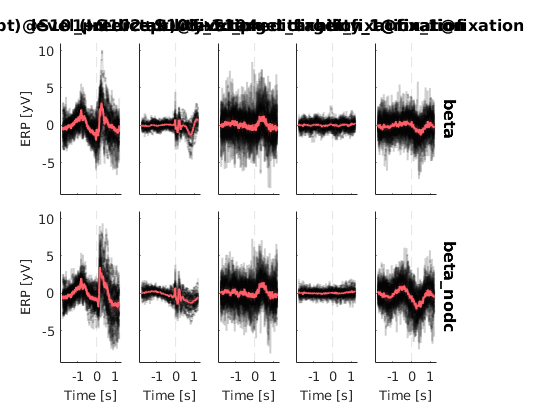

stat_summary(g,'geom','area','type','bootci');
draw(g);

## Plot a single channel - alternative version

This version results in the identical plot but is slower. The reason is, that the dc_plotParam was written to visualize 1st level (single subject) results. The above version only works if no *converted spline* predictor exists. If a converted spline is found, each subject has to be plotted iteratively, which makes it more slow and less useful to postprocess. So try the above first, if its not working try this alternate version. 

cfg = [];
cfg.chan = 40; % CPz
cfg.add_intercept = 0;
cfg.baseline = [min(d2nd.times) 0];

% Plot each subject individually and keep the gramm-object around
% to update it each round
for s = 1:size(d2nd.beta,4)
    d2nd2 = d2nd;
    d2nd2.beta = d2nd2.beta(:,:,:,s);
    d2nd2.beta_nodc = d2nd2.beta_nodc(:,:,:,s);
    g = dc_plotParam(d2nd2,cfg);
    cfg.gramm = g; %after the first subject keep this around
end

plotting all parameters


performing baseline correctionperforming baseline correction

plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared


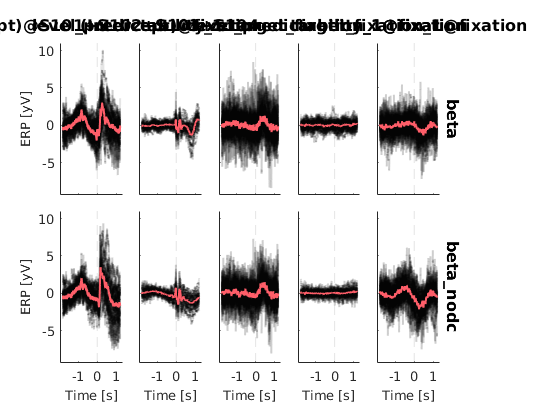

plotting all parameters


performing baseline correctionperforming baseline correctionNew X or Y of different size given, all data from first gramm cleared



% Same as above, make all lines black and transparent
for a = g.facet_axes_handles(:)'
    a = get(a,'Children');
    for child = a'
        if child.LineStyle == '-'
            child.Color = [0 0 0 0.1];
        end
    end
end


% we need to manually add the mean. Adding the bootstrapped CI
% is certainly possible using the gramm toolbox, but more involved
% We clearly recommend the above way of doing things.
d2nd2 = d2nd;
d2nd2.beta = mean(d2nd2.beta(:,:,:,:),4);
d2nd2.beta_nodc = mean(d2nd2.beta_nodc(:,:,:,:),4);

g = dc_plotParam(d2nd2,cfg);

## Statistics using Threshold-Free-Cluster-Enhancement (TFCE)

% This function calculates a channel matrix that can either be used for default cluster-permutation tests
% as implemented in the LIMO toolbox, or using the ept-tfce toolbox
% The matrix contains a description on which 
[neighmat, ept_tfce_nb] = chanloc2neighbourstruct(d2nd.chanlocs,50);

% Average amount of neighbours:
mean(sum(neighmat))

ans =        5.5938


Run the analysis using the ept-tfce toolbox

cfg = [];
cfg.chan = 1:63;
cfg.pred = 4; % predictability at a target-word

% subselect channels & predictor  
data = squeeze(d2nd.beta(cfg.chan,:,cfg.pred,:));

% baseline correction
data = bsxfun(@minus,data,mean(data(:,d2nd.times<0,:),2));

% do the statistics
% this is a customized version of the original ept_tfce_diff function
[res,info] = be_ept_tfce_diff(struct('nperm',500,'neighbours',ept_tfce_nb(cfg.chan,:)),permute(data,[3 1 2]));

Calculating Actual Differences...


Calculating Permutations...


Done


Calculating P-Values and Saving...


All done!


Elapsed time is 74.738691 seconds.


Peak significance found at channel 48 at sample 1134: max-t-val(24) = 6.037, p = 0.001992


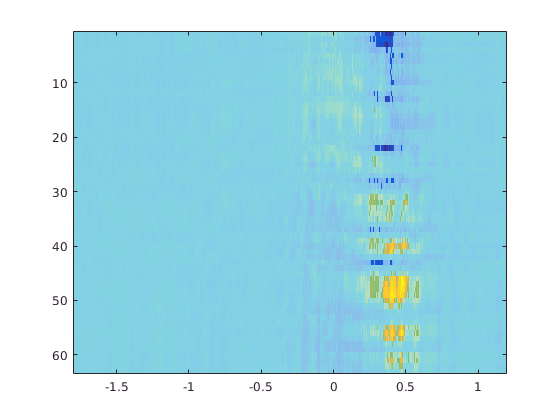

% plot it :)
figure,
h = imagesc(d2nd.times,1:63, res.TFCE_Obs);
set(h,'AlphaData',(res.P_Values<0.05)*0.5+0.5)

This concludes the tutorial on doing group level analyses. 